## Example #1 : regular tetrahedron

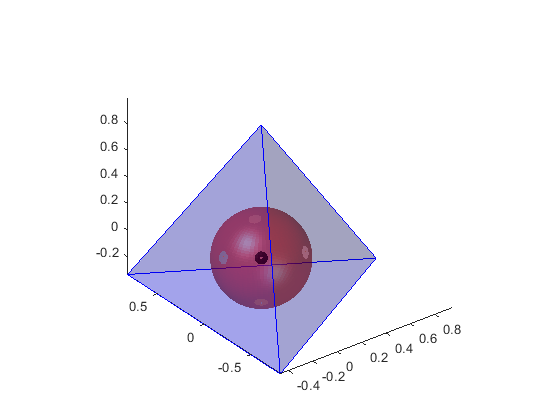

I = 	1.0e+-16 *

         0         0    0.2776


r = 0.3333

P = [0            0          1;...
     2*sqrt(2)/3  0         -1/3;...
      -sqrt(2)/3  sqrt(6)/3 -1/3;...
      -sqrt(2)/3 -sqrt(6)/3 -1/3];

F = [1 2 3; 1 3 4; 1 4 2; 2 4 3];
nb_samples = 60;
[I,r] = regular_polyhedron_insphere(P,F,nb_samples,true) % expected : I = [0 0 0]; r = 1/3;

## Example #2  : cube / hexahedron

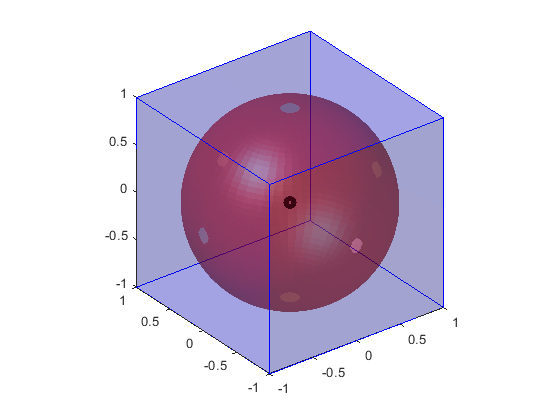

I =      0     0     0


r = 1

P = [ 1  1  1;...
     -1  1  1;...
     -1 -1  1;...
      1 -1  1;...
      1  1 -1;...
     -1  1 -1;...
     -1 -1 -1;...
     1 -1 -1];

F = [1 2 3 4;...
     8 7 6 5;...
     1 4 8 5;...
     2 1 5 6;...
     3 2 6 7;...
     4 3 7 8];

nb_samples = 60;
[I,r] = regular_polyhedron_insphere(P,F,nb_samples,true) % expected : I = [0 0 0]; r = 1

## Example #3  : octahedron

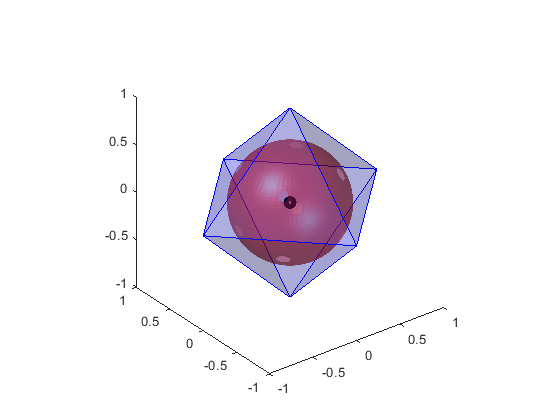

I =      0     0     0


r = 0.5774

P = [ 1  0  0;...
      0  1  0;...
     -1  0  0;
      0 -1  0;...
      0  0  1;...
      0  0 -1];

F = [1 2 5;...
     2 3 5;...
     3 4 5;...
     4 1 5;...
     1 6 2;...
     2 6 3;...
     3 6 4;...
     4 6 1];

nb_samples = 60;
[I,r] = regular_polyhedron_insphere(P,F,nb_samples,true) % expected : I = [0 0 0]; r = sqrt(3)/3